# prolem  set 3

## Prolem 1

## a

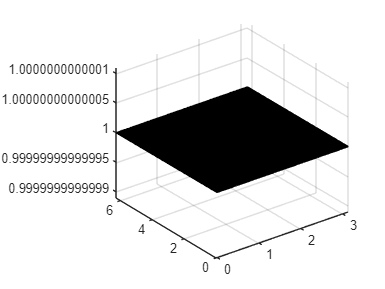


% ketpn = cos(theta/2) * ketpz + exp(i * phi) * sin(theta/2) * ketnz;
% brapn = branz * cos(theta/2) + branz * (-i * phi)*sin(thet/2)
% braketpn = cos(theta/2) .^2 * braketpn + e^(phi * (-i+i)) * sin(theta/2) .^2 * braketnz
thetalist = linspace(0, pi, 100); 
philist = linspace(0, 2*pi, 100); 
[theta, phi] = meshgrid(thetalist, philist);

z = sin(theta/2).^2 + cos(theta/2).^2;
surf(theta, phi, z)

## b

pz = [1 ; 0]; 
nz = [0 ; 1];
px = 1/sqrt(2) * pz + 1/sqrt(2) * nz;
py = 1/sqrt(2) * pz + 1i/sqrt(2) * nz;
syms a b; 
assume(b, "real");
disp('theta x = pi/2, phi x = 0');

theta x = pi/2, phi x = 0


disp('theta y = -pi/2, phi y = -pi/2');

theta y = -pi/2, phi y = -pi/2


disp('theta y = pi/2, phi y = pi/2');

theta y = pi/2, phi y = pi/2


[thetax, phix] = solve(cos(a/2) == 1/sqrt(2), exp(1i * b) * sin(a/2) == 1/sqrt(2))

$$thetax = \left(\begin{array}{c} \frac{\pi }{2}\\ -\frac{\pi }{2} \end{array}\right)$$

$$phix = \left(\begin{array}{c} 0\\ -\log\left(-\sqrt{2}\right)\,\mathrm{i}+\frac{\log\left(2\right)\,\mathrm{i}}{2} \end{array}\right)$$

[thetay, phiy] = solve(cos(a/2) == 1/sqrt(2), exp(1i * b) * sin(a/2) == 1i/sqrt(2))

$$thetay = \left(\begin{array}{c} -\frac{\pi }{2}\\ \frac{\pi }{2} \end{array}\right)$$

$$phiy = \left(\begin{array}{c} -\frac{\pi }{2}\\ \frac{\pi }{2} \end{array}\right)$$

## c

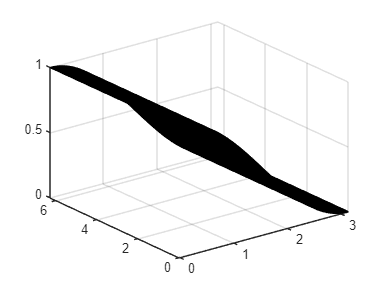

% |<pz | cos(theta/2) | pz> + exp(iphi)sin(theta/2) | nz>|^2 = |cos(theta/2)|^2
thetalist = linspace(0, pi, 100); 
philist = linspace(0, 2*pi, 100);
[theta, phi] = meshgrid(thetalist, philist); 
z = abs(cos(theta/2)).^2;
surf(theta, phi, z)

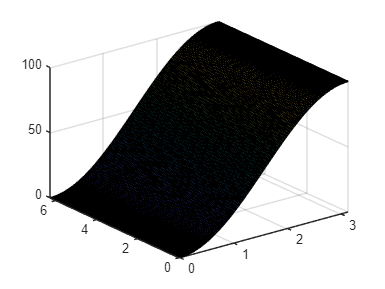

% |<nz | cos(theta/2) | pz> + exp(iphi)sin(theta/2) | nz>|^2 = |exp(iphi)sin(theta/2)|^2
[theta, phi] = meshgrid(thetalist, philist);
z = abs(exp(1i * phi) * sin(theta/2).^2);
surf(theta, phi, z)

## prolem 2

## a

v = [1 (sqrt(3)/(2*sqrt(2))+1i*sqrt(3)/(2*sqrt(2))) ; (sqrt(3)/(2*sqrt(2))-1i*sqrt(3)/(2*sqrt(2))) 2]

v =    1.0000 + 0.0000i   0.6124 + 0.6124i
   0.6124 - 0.6124i   2.0000 + 0.0000i


v1 = v'

v1 =    1.0000 + 0.0000i   0.6124 + 0.6124i
   0.6124 - 0.6124i   2.0000 + 0.0000i


v2s = conj(v.')

v2 =    1.0000 + 0.0000i   0.6124 + 0.6124i
   0.6124 - 0.6124i   2.0000 + 0.0000i


## b

[lambdaket, lambda] = eig(v)

lambdaket =    0.6124 + 0.6124i   0.3536 + 0.3536i
  -0.5000 + 0.0000i   0.8660 + 0.0000i


lambda =     0.5000         0
         0    2.5000


e1 = lambdaket(: ,1)

e1 =    0.6124 + 0.6124i
  -0.5000 + 0.0000i


e2 = lambdaket(: ,2)

e2 =    0.3536 + 0.3536i
   0.8660 + 0.0000i


lambdaket([1, 2], 1)' *  lambdaket([1, 2], 2)

ans = -8.3267e-17 + 2.7756e-17i

val = e1'*e2

val = -8.3267e-17 + 2.7756e-17i

## c

Ap = (e1' * v * e1)

Ap = 0.5000

An = (e2' * v * e2)

An = 2.5000

var1 = (e1' * v^2 * e1) - Ap.^2

var1 = 5.5511e-17 + 1.3878e-17i

var2 = (e2' * v^2 * e2) - An.^2

var2 = 8.8818e-16

disp('the state collapses the eigenstate of the operator, with the observation from the eigenvalue')

the state collapses the eigenstate of the operator, with the observation from the eigenvalue


## prolem 3

## a

I = [1 0 ; 0 1];
X = [0 1 ; 1 0];
Y = [0 -1i ; 1i 0];
Z = [1 0 ; 0 -1];
syms a b c d
disp (solve(v == a * I + b * X + c * Y + d * Z))

    a: 3/2
    b: (2^(1/2)*3^(1/2))/4
    c: -(2^(1/2)*3^(1/2))/4
    d: -1/2



[a b c d] = solve(v == a * I + b * X + c * Y + d * Z)

$$a = \frac{3}{2}$$

$$b = \frac{\sqrt{2}\,\sqrt{3}}{4}$$

$$c = -\frac{\sqrt{2}\,\sqrt{3}}{4}$$

$$d = -\frac{1}{2}$$

[phi, theta,  z] = cart2sph(b, c, d)

$$phi = -\frac{\pi }{4}$$

$$theta = -\frac{\pi }{6}$$

$$z = 1$$

theta = pi/2-theta

$$theta = \frac{2\,\pi }{3}$$

phi = 2*pi+phi

$$phi = \frac{7\,\pi }{4}$$

abs(lambdaket(:, 2)'*[cos(theta/2) ; exp(1i*phi) * sin((theta/2))])

$$ans = 1$$